Import image

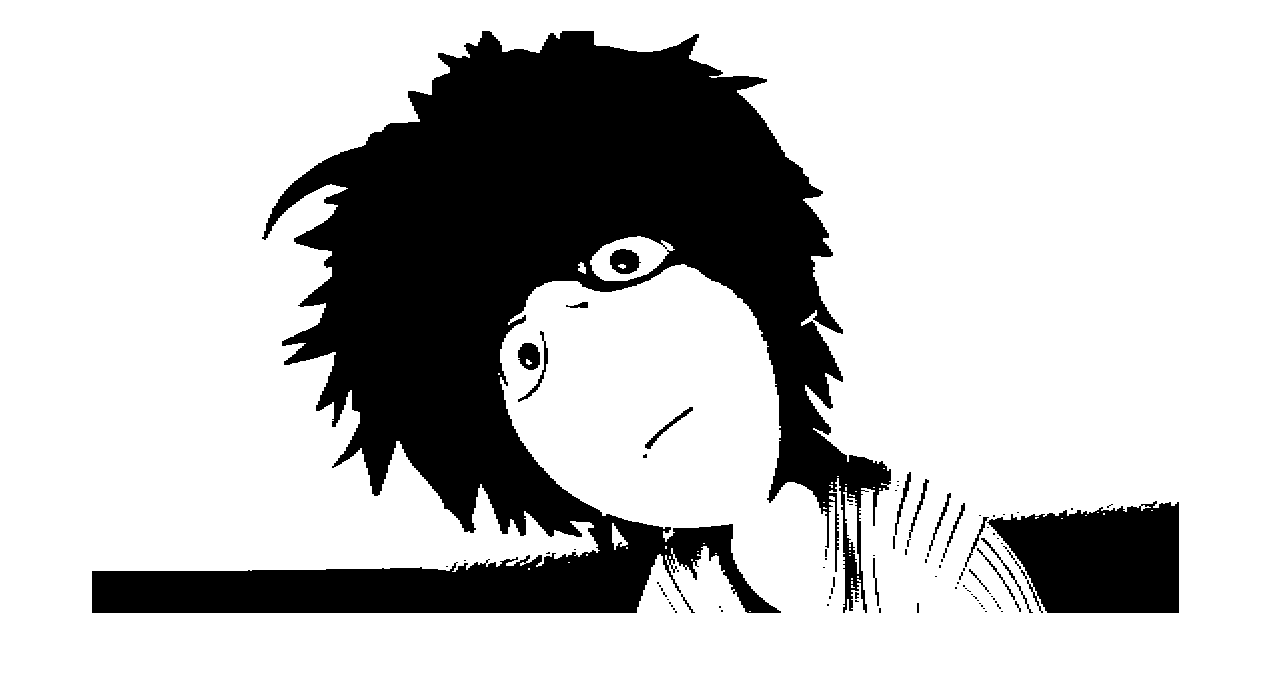

imdata = imread('https://images0.cnblogs.com/blog/614265/201408/241708117531878.png');
I=im2bw(imdata);
I=I+0;
imshow(I)

salt and pepper

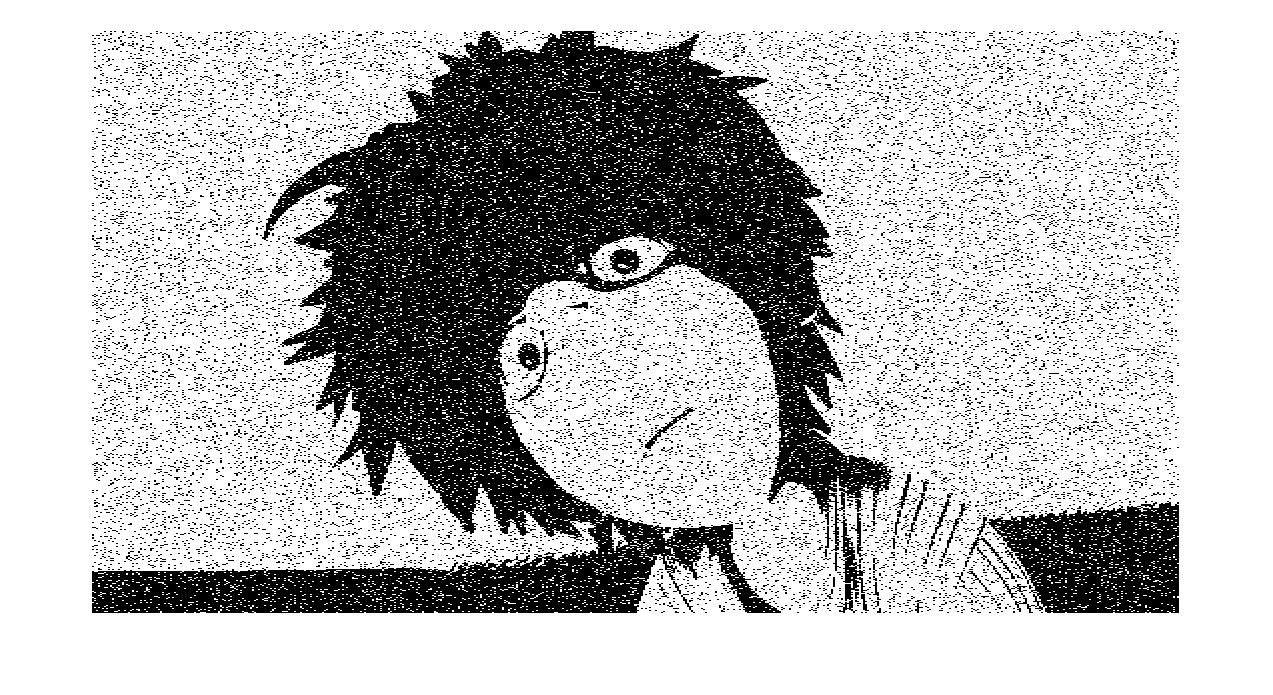

J = imnoise(I,'salt & pepper',0.2);
imshow(J)

Initialize

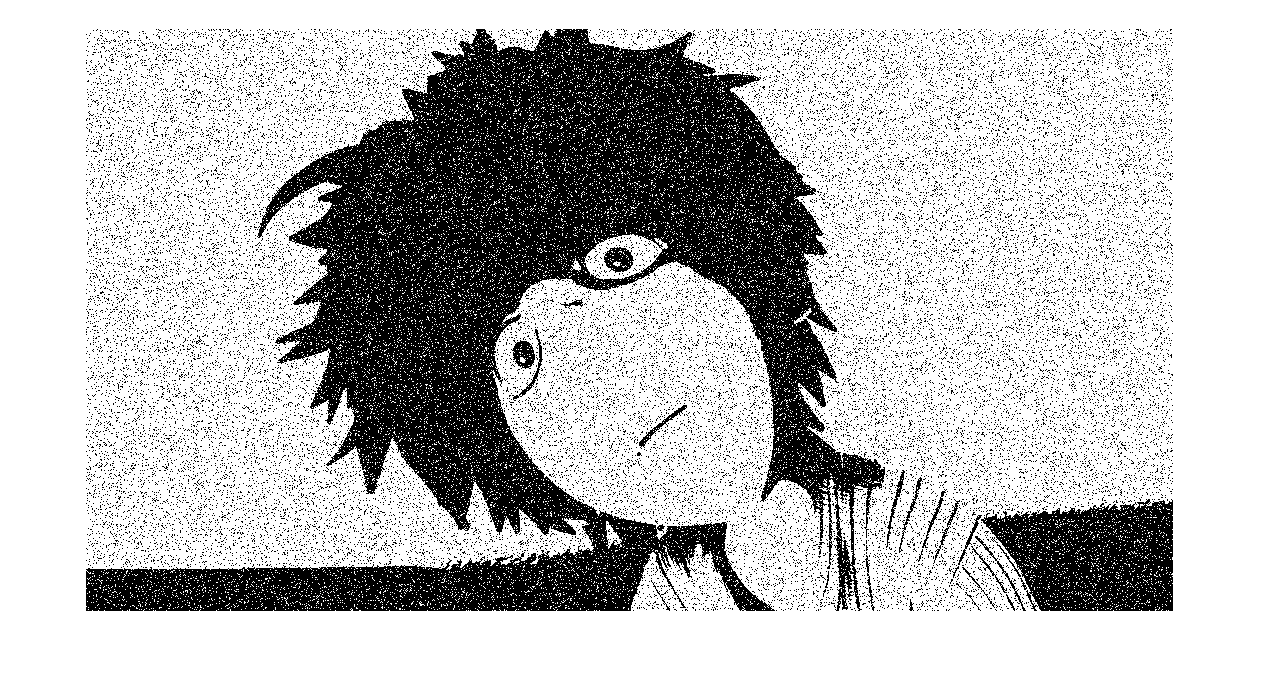

parfor i = 1 : 582
    for j =1:1087
        if dist(J(i,j),1)<dist(J(i,j),0)
            J(i,j)=1;
        else
            J(i,j)=0;
        end
    end
end
J(find(J==0))=-1;
imshow(J)

Denoise

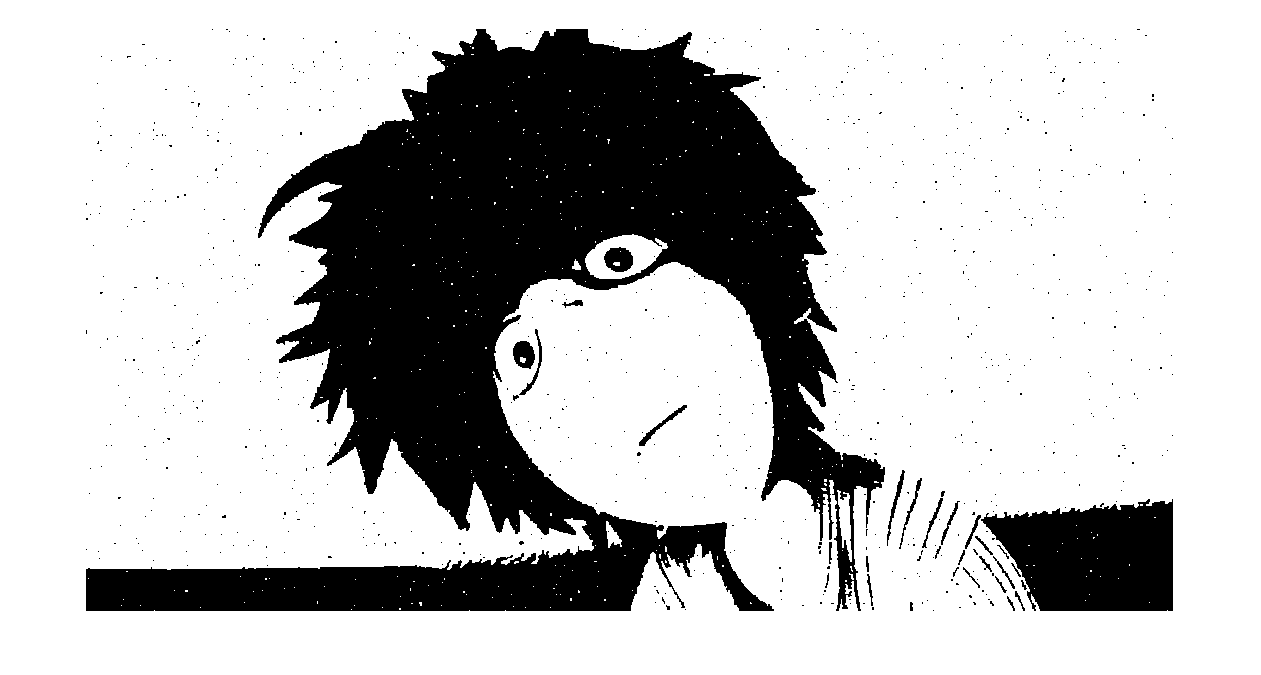

[M,N]=size(J);
T=J;
J=T;
for i = randperm(M,M)
    for j = randperm(N,N)
        if E(i,j,1,linju(i,j,M,N,J),J)<E(i,j,-1,linju(i,j,M,N,J),J)
            J(i,j)=1;
        else
            J(i,j)=-1;
        end
    end
end
figure
imshow(J)

Order

for i = 1:M
    for j = 1:N
        if E(i,j,1,linju(i,j,M,N,J),J)<E(i,j,-1,linju(i,j,M,N,J),J)
            J(i,j)=1;
        else
            J(i,j)=-1;
        end
    end
end
figure
imshow(J)

Guassian noise

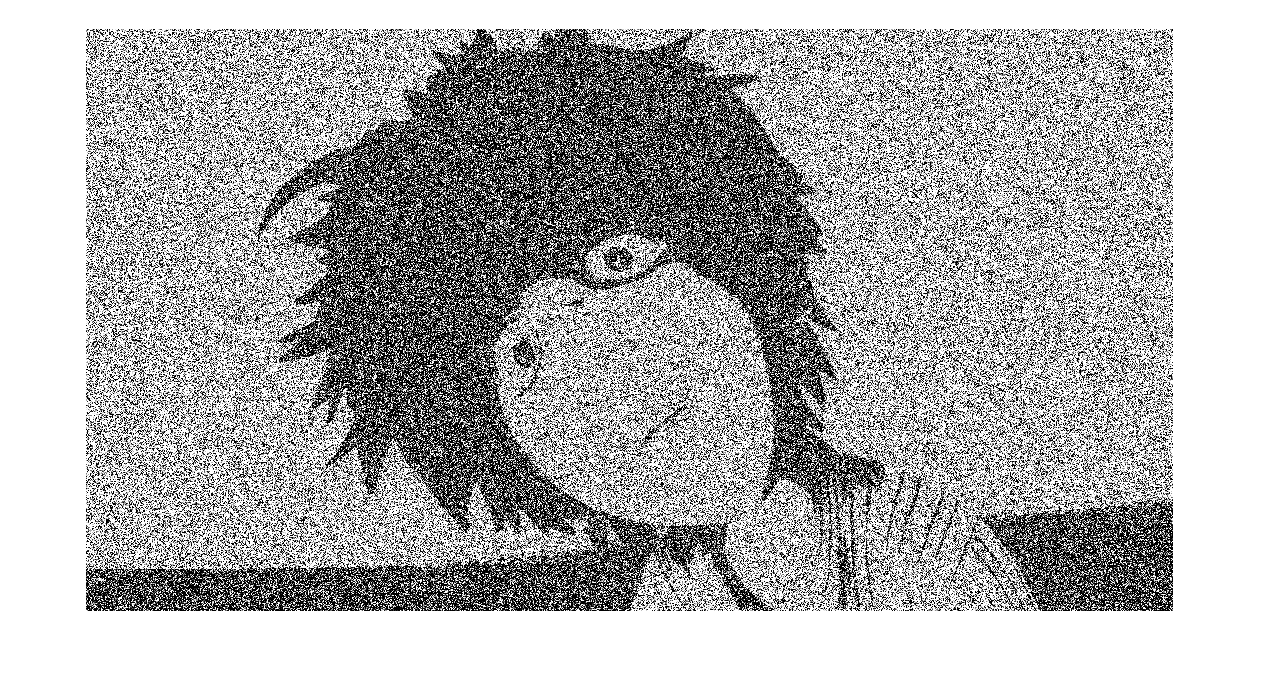

r = normrnd(0,1,size(I));
J=I+0;
J = I+r;
imshow(J)

Denoise

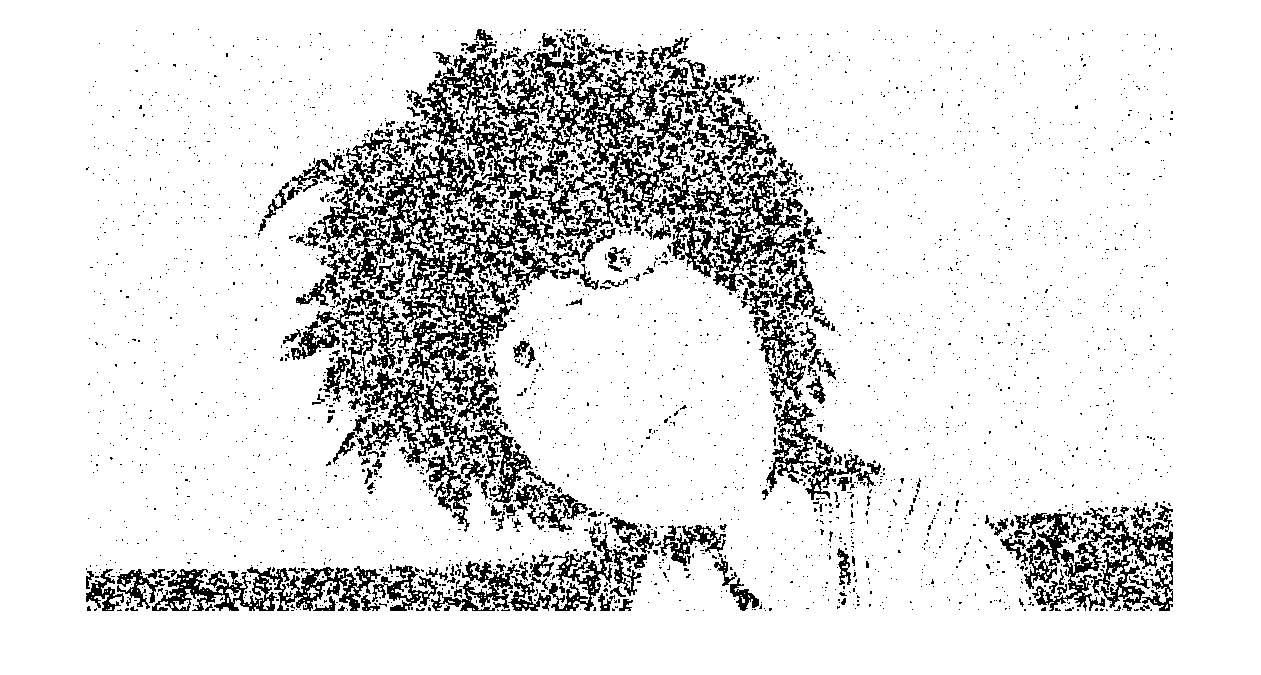

[M,N]=size(J);
T=J;
J=T;
for i = randperm(M,M)
    for j = randperm(N,N)
        if E(i,j,1,linju(i,j,M,N,J),J)<E(i,j,-1,linju(i,j,M,N,J),J)
            J(i,j)=1;
        else
            J(i,j)=-1;
        end
    end
end
figure
imshow(J)

Order

for i = 1:M
    for j = 1:N
        if E(i,j,1,linju(i,j,M,N,J),J)<E(i,j,-1,linju(i,j,M,N,J),J)
            J(i,j)=1;
        else
            J(i,j)=-1;
        end
    end
end
figure
imshow(J)

Gibbs Ising

for k = 1:20
    for i = randperm(M,M)
        for j = randperm(N,N)
            p = exp(E(i,j,1,linju(i,j,M,N,J),J))/(exp(E(i,j,1,linju(i,j,M,N,J),J))+exp(E(i,j,-1,linju(i,j,M,N,J),J)));
            if p<rand(1)
                J(i,j)=1;
            else
                J(i,j)=-1;
            end
        end
    end
    k
end
figure
imshow(J)

s

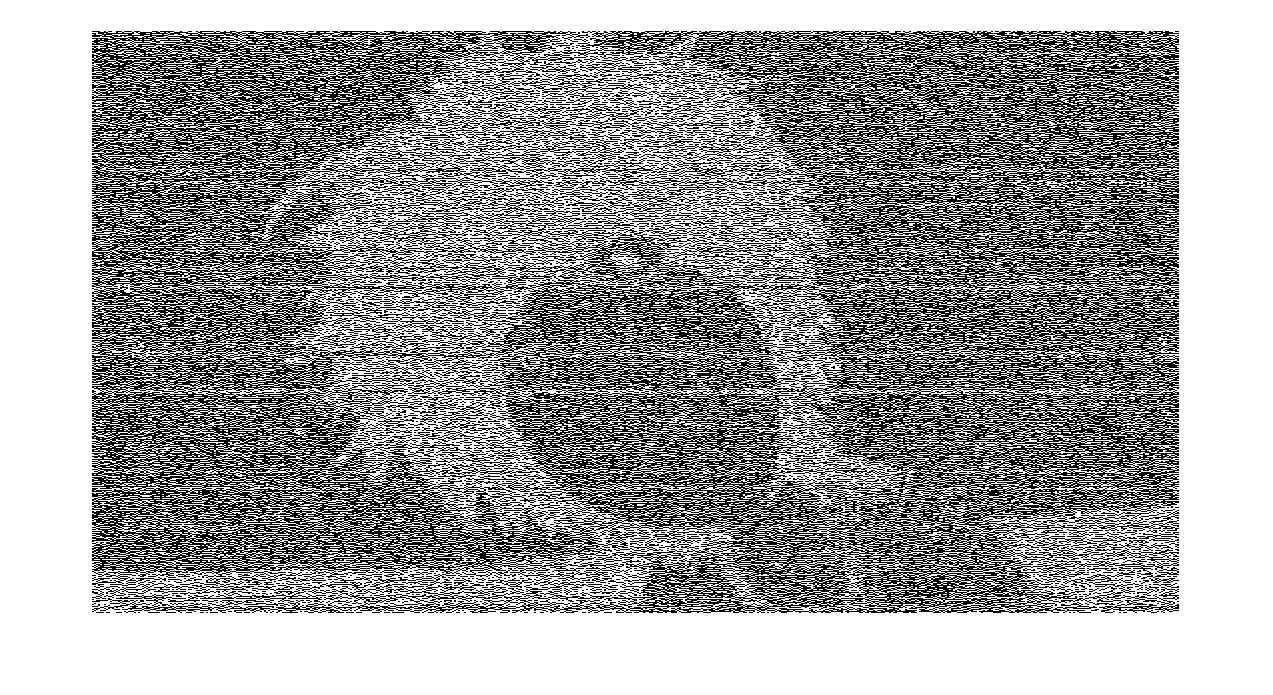

exp(E(i,j,1,linju(i,j,M,N,J),J))/(exp(E(i,j,1,linju(i,j,M,N,J),J))+exp(E(i,j,-1,linju(i,j,M,N,J),J)))

function result = E(i,j,k,set,J)
    h=0;beta=1;sigma=0.1;
    %temp = sum(J([set(1,:),set(2,:)])*k);
    temp=sum(set*k);
    %result = h*(sum(set)+k)-beta*temp-sigma*k*J(i,j);%-beta*(sum(set)+k)
    result = h*k-beta*temp-sigma*k*J(i,j);%the result is basically the
    %same
end
function Set = linju(i,j,M,N,J)
        if (i==1&&j==1)
            n = [1,2;2,1];
        elseif i==1 && j==N
            n = [1,N-1;2,N];
        elseif i==M&&j==1
            n = [M-1,1;M,2];
        elseif i==M&&j==N
            n = [M,N-1;M-1,N];
        elseif i==1
            n = [1,j-1;1,j+1;2,j];
        elseif i==M
            n = [M,j-1;M,j+1;M-1,j];
        elseif j==1
            n = [i-1,1;i+1,1;i,2];
        elseif j==N
            n = [i-1,N;i+1,N;i,N-1];
        else
            n=[i-1,j;i+1,j;i,j-1;i,j+1];
        end
    Set =[];
    for i = 1:length(n)
        Set = [Set J(n(i,1),n(i,2))];
    end
end